# Resolución de expresiones y ecuaciones

Existen diferentes funciones para la resolución de expresiones y ecuaciones tanto para encontrar raíces, respuestas numéricas, sistemas lineales y no lineales, etc.

Sin embargo, en este capítulo la función que destacará será `solve`.

## Función `solve`

Cuando se utiliza la función `solve`, el resultado (escalar o vector) es también simbólico. Por ende, antes de utilizar la salida se debe convertir a dato numérico mediante alguna función de esta clase de datos (`double`, `single`, `int8`, etc.).

### Para expresiones con una variable

Cuando se usa con una expresión, la función `solve` iguala la expresión a cero y resuelve para las raíces.

clear

E1 = str2sym('x-3')
solve(E1)

Por supuesto que si la expresión tiene más raíces la respuesta será un arreglo bidimensional.

E2 = str2sym('x^2+9')
solve(E2)

Además, la expresión puede no ser tan sencilla.

E3 = str2sym('a*x^2+b*x+c')
solve(E3)

Sin embargo, si la expresión no lleva por variable independiente **x**, se puede especificar cuál será la variable ingresando un segundo argumento a la función `solve`. Previamente esta variable debe haberse definido.

a = sym('a')
solve(E3,a)

### Para expresiones con múltiples variables

La función `solve` es particularmente útil con expresiones simbólicas con múltiples variables, puesto que nos permite ingresar como segundo argumento la variable respecto a la cual se quiere resolver.

E4 = str2sym('P=P0*exp(r*t)')
t = sym('t')

solve(E4,t)

Como se puede observar, la función `solve` ha despejado la variable **t** de la ecuación original.

### Para ecuaciones

También es posible determinar las raíces de una ecuación directamente.

E5 = str2sym('5*x^2+6*x+3=10')
solve(E5)

### Consideración cuando se utiliza la función `solve`

Hasta ahora no se ha mencionado, pero MATLAB utiliza Maple para toda el álgebra simbólica y los cálculos que se pueden hacer en esta.

Puesto que las capacidades simbólicas de MATLAB se basan en Maple, necesita entender cómo Maple maneja los cálculos. Maple reconoce dos tipos de datos numéricos: enteros (`int`) y punto flotante (`double` para MATLAB, `float` en otros lenguajes).

Los números punto flotante se consideran aproximaciones y usan punto decimal, mientras que los enteros son exactos y se representan sin punto decimal. En los cálculos que usan enteros, Maple fuerza una respuesta exacta, que resulta en fracciones. Si hay punto decimal (números punto flotante) en los cálculos Maple, el resultado también será una aproximación y contendrá punto decimal.

Maple tiene por defecto 32 cifras significativas, de modo que en los resultados se muestran 32 dígitos.

Considere un ejemplo que usa `solve`. Si la expresión usa números punto flotante (`double`), se obtiene el siguiente resultado:

clear

eqDouble = str2sym('5.0*x^2.0+6.0*x-7.0')
solve(eqDouble)

Si la expresión usa enteros (`int`), los resultados son fracciones:

eqInt = str2sym('5*x^2+6*x-7')
solve(eqInt)

## Resolución de sistemas de ecuaciones

Para resolver un sistema de ecuaciones con la función `solve` basta con definir las ecuaciones e ingresarlas en la función.

clear

syms x y z
eq1 = 3*x + 2*y - z == 10
eq2 = -x + 3*y + 2*z == 5
eq3 = x - y - z == -1

sol = solve(eq1,eq2,eq3)

Las respuestas son devueltas en una estructura.

sol.x
sol.z

Pero estas soluciones son simbólicas, por ende, se deben convertir a numéricas para poder trabajar con estas.

X = double(sol.x)

Aunque si se quiere, directamente se puede igualar las soluciones a un arreglo salida.

[xSol, ySol, zSol] = solve(eq1,eq2,eq3)

No obstante, las respuestas siguen siendo simbólicas.

**Nota:** Los resultados se asignan alfabéticamente. Por ejemplo, si las variables que se usaron en las expresiones son **q**, **x** y **p**, los resultados se regresarán en el orden **p**, **q**, **x**, independientemente de los nombres que se hayan asignado para los resultados.

### Sistemas de ecuaciones con función `solve` VS. solución matricial

Recordemos que para resolver un sistema de ecuaciones se vio en capítulos anteriores que es posible utilizar la matriz inversa de la matriz de coeficientes (aunque no se recomieda) y también con la división izquierda (esta sí se recomienda).

Ahora vemos que con la función `solve` también es posible solucionar un sistema de ecuaciones. Sin embargo, ¿cuál es la diferencia entre un método y otro? Pues bien:

- Resolver un sistema de ecuaciones matricialmente es más eficiente que utilizar la función `solve`.

- Pero un sistema de ecuaciones matricial debe ser lineal, esa es su limitación.

- No obstante, un sistema de ecuaciones no lineal se puede solucionar con la función `solve`.

## Tabla resumen del uso de la función `solve`

A continuación, se muestran algunas aplicaciones de la función `solve`.

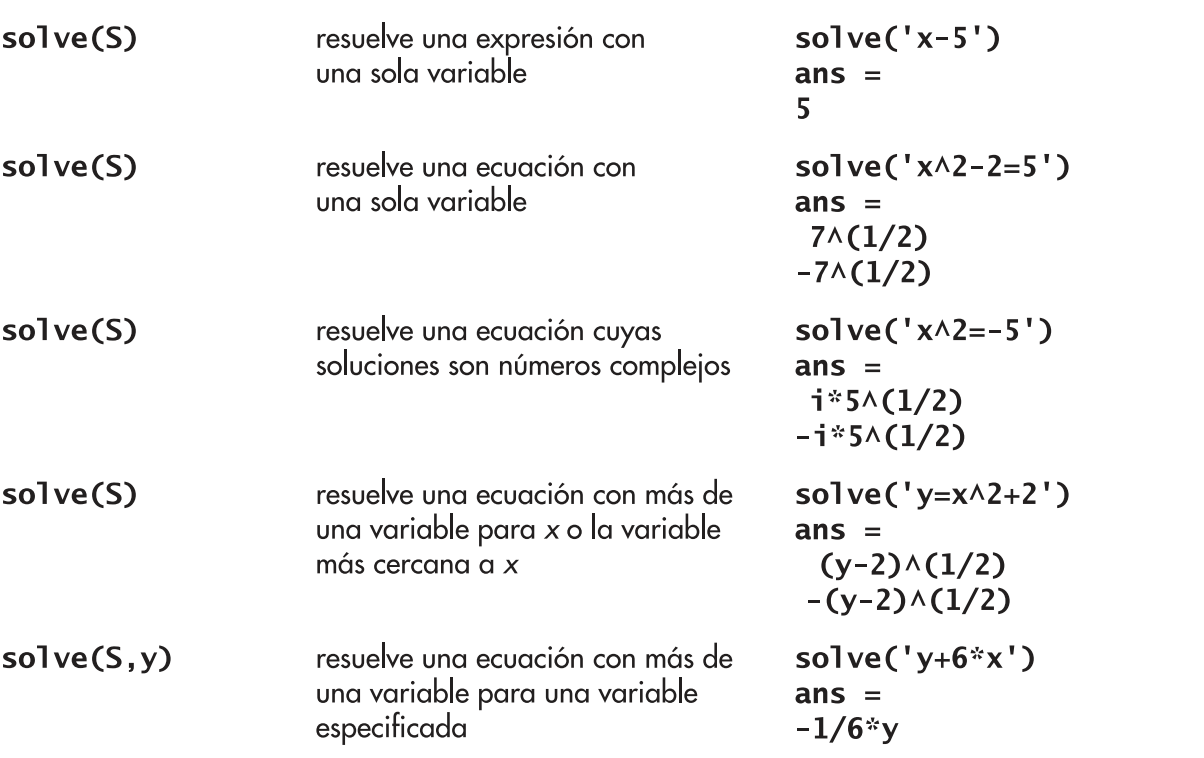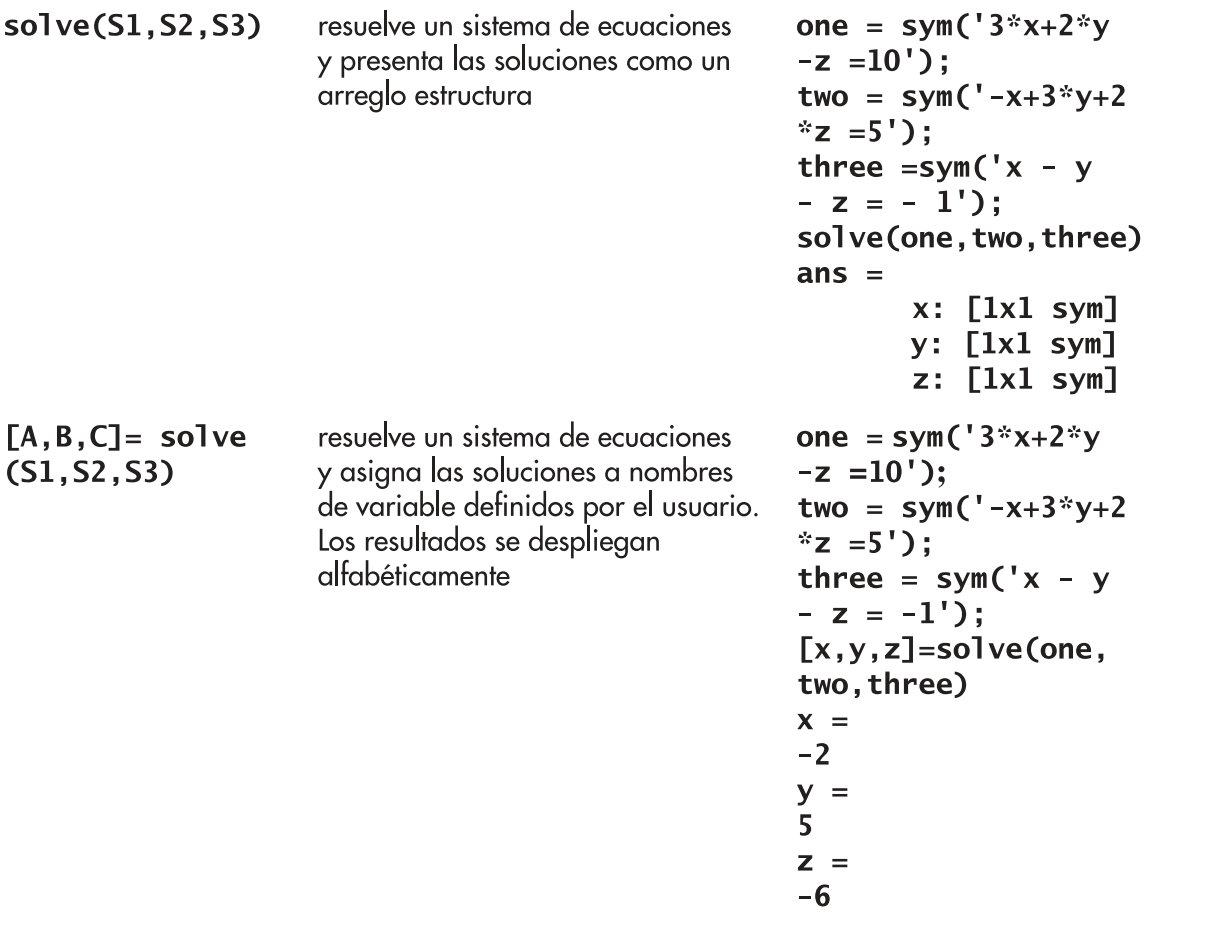

## Sustitución/evaluación de expresiones

También resulta útil renombrar variables o evaluarlas. Para esto sirve la función `subs`.

### Renombrar variables

Para renombrar variables se deben ingresar la expresión, la anterior variable y la nueva variable en la función `subs`. 

clear

eq = str2sym('a*x^2 + b*x + c')

subs(eq,'x','y')

En este caso hemos cambiado la variable simbólica **x** por la variable simbólica **y**.

**Nota:** Si las variables simbólicas se las ha definido previamente no es necesario ingresarlas entre apóstrofes.

### Evaluar una expresión

Siguiendo la misma estructura para renombrar variables se puede evaluarlas, en este caso el último parámetro es el valor donde se quiere evaluar.

subs(eq,'x',2)

No obstante, también se puede evaluar múltiples variables simbólicas.

EQ = subs(eq,{'a','b','c'},{1,2,3})

A su vez, también se puede evaluar varios valores.

numbers = 1:5;

subs(EQ,'x',numbers)